# Removing Electrical Line Noise

- ac frequency is typically 60hz (some countries 50hz, as in this dataset)

### Load the dataset

load ../datasets/lineNoiseData.mat;
len = length(data);
t = (0:len-1)/srate;

### Compute the power spectrum

power_spectrum = abs(fft(data)/len).^2;
hz = linspace(0,srate,len);

### Plot

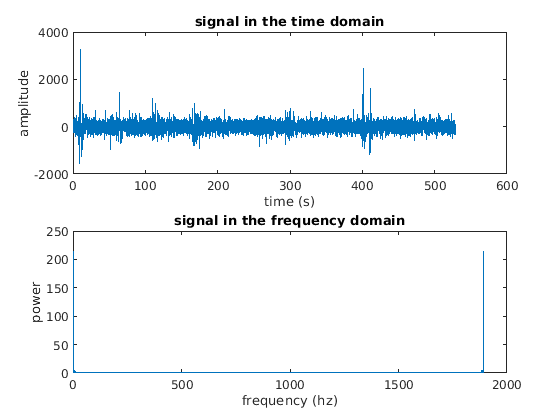

f1 = figure(1); clf;

subplot(211);
plot(t, data);
xlabel("time (s)");
ylabel("amplitude");
title("signal in the time domain");

subplot(212);
plot(hz, power_spectrum);
xlabel("frequency (hz)");
ylabel("power");
title("signal in the frequency domain");